# ECSE 343 Final Exam Question1 (15 Marks)

Posted at 9:00AM April 19, 2021

Due at 9:00AM April 22, 2021

**This final has three Questions. Each question is submitted as a seperate 'assignment'.** 

## **Question 1**

Your are given the results of an experpiment which are stored in Q1data.mat

Note that given the type of experiment, you know that YQ1data contains zero-mean gaussian noise. 

You may run the following code in order to display the data (make sure Q1data.mat is in your working directory):

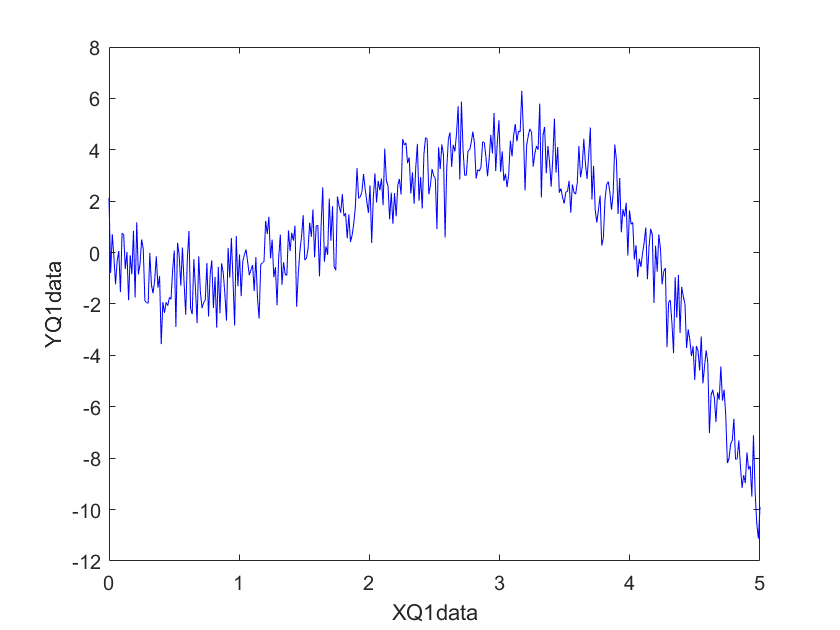

clear all
clf
load Q1data
plot(XQ1data,YQ1data,'b')
xlabel('XQ1data')
ylabel('YQ1data')

**Part 1 (8 Points)**

Use the techniques we studied in this course in order to find a plot a better estimate of YQ1data and store it in YQ1est. You may use (if needed) the following matlab builtin functions: qr, lu, chol, svd, eig, polyval, and the '\' operator as in x = A\b. Include and run your code below

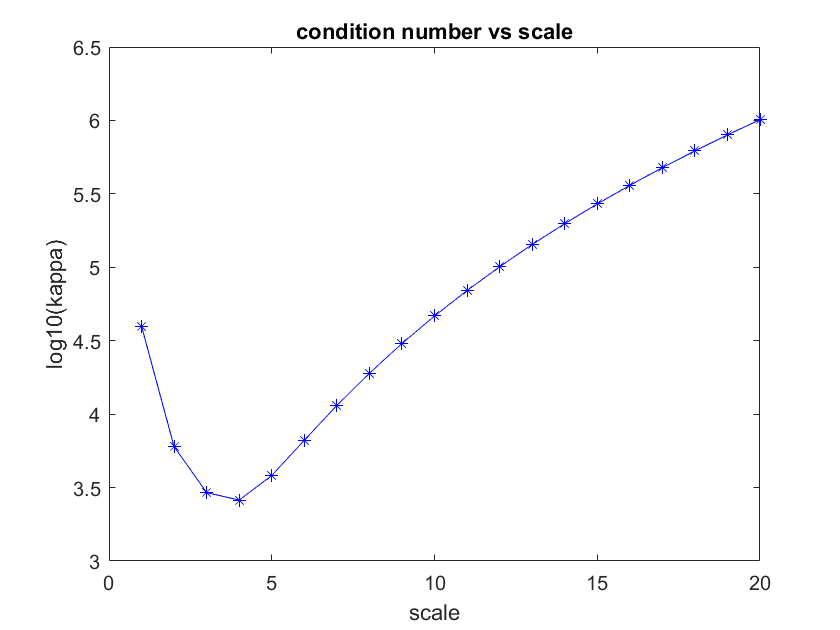

% Load and plot original data
clear all
clf
load Q1data

%%% Your code to compute YQ1est should go below
%%% testing scale
scale_max = 20;
deg = 5; % Degree
for i = 1:scale_max
    As = Least_squared_scaled(deg,i,XQ1data);
    cond_num(i)=cond(As);
end
figure(1)
plot(1:scale_max,log10(cond_num),'b-*')
ylabel('log10(kappa)');
xlabel('scale');
title('condition number vs scale')

%%% Q1 solution
XQ1data = XQ1data/4 %scaling

XQ1data =          0    0.0031    0.0063    0.0094    0.0125    0.0157    0.0188    0.0219    0.0251    0.0282    0.0313    0.0345    0.0376    0.0407    0.0439    0.0470    0.0501    0.0533    0.0564    0.0595    0.0627    0.0658    0.0689    0.0721    0.0752    0.0783    0.0815    0.0846    0.0877    0.0909    0.0940    0.0971    0.1003    0.1034    0.1065    0.1096    0.1128    0.1159    0.1190    0.1222    0.1253    0.1284    0.1316    0.1347    0.1378    0.1410    0.1441    0.1472    0.1504    0.1535


powers=0:deg;
YQ1est = zeros(size(YQ1data));
A = PolynomialMatrix(XQ1data,deg)

A =     1.0000         0         0         0         0         0
    1.0000    0.0031    0.0000    0.0000    0.0000    0.0000
    1.0000    0.0063    0.0000    0.0000    0.0000    0.0000
    1.0000    0.0094    0.0001    0.0000    0.0000    0.0000
    1.0000    0.0125    0.0002    0.0000    0.0000    0.0000
    1.0000    0.0157    0.0002    0.0000    0.0000    0.0000
    1.0000    0.0188    0.0004    0.0000    0.0000    0.0000
    1.0000    0.0219    0.0005    0.0000    0.0000    0.0000
    1.0000    0.0251    0.0006    0.0000    0.0000    0.0000
    1.0000    0.0282    0.0008    0.0000    0.0000    0.0000


cond(A)

ans = 2.5988e+03

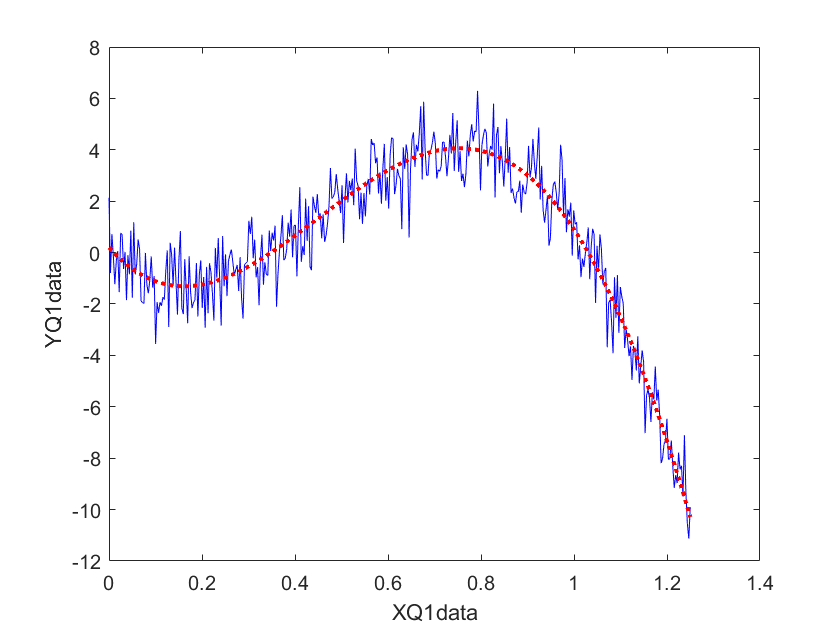

% Compute the coefficients 
[Q,R] = qr(A);
Ar = R\(Q'*YQ1data');

for I = 1:length(powers)
    YQ1est = YQ1est + Ar(I)*XQ1data.^powers(I);
end

figure(2)
% Plot the results of your estimate and compare to original data
% The code below assumes you have already computed YQ1est 
plot(XQ1data,YQ1data,'b')
xlabel('XQ1data')
ylabel('YQ1data')
hold on
plot(XQ1data,YQ1est,'r:','LineWidth',2)

function M = PolynomialMatrix(x,n)
% write your code here
 % n is the degree of the polynomila
 % x is the vector of input data
 powers=0:n; 
     for I = 1:length(powers)
         M(:,I)=x.^powers(I);
     end
end

function M = Least_squared_scaled(deg,scale,x)
% write your code here
 % n is the degree of the polynomila
 % x is the vector of input data
 powers=0:deg; 
 x_new = x./scale;
     for I = 1:length(powers)
         M(:,I)=x_new.^powers(I);
     end
end

**Part 2 (4 Marks)**

Describe using equations and words the the algorithm/techniques us used in part 1. Justify your choices methods used and for the parameters you used in your models. You may type your answer below. or include it in an attached pdf file. If you choose the latter, please put a note below indicating that the answer is in the attached pdf file.

Description of algorithm: I first scale XQ1data by dividing it by a scaling number which I choose to be 4. Then I input the degree=5 and power range of the polynomial matrix, and the power range is defined by degree. Next, I initialize an empty array for YQ1est and the size is set to the size of YQ1data. Then, I use a funtion to generate the polynomial matrix by inputting XQ1data and degree. We use the following equation to calculate our polynomial matrix M.

   
$$\matrix{   Input,, x  | &  x_0  &x_1  & x_2& x_3 &\dots  & x_{m-1}& x_m \cr
Output, y| &  y_0 & y_1& y_2 & y_3 & \dots & y_{m-1}&y_m
}$$


we can fit a $n^{\textrm{th}}$degree polynomial, $p\left(x\right)=a_0 +a_1 x+a_{2\;} x^{2\;} +a_3 x^3 +\cdots +a_{n\;} x^n$. To find the coefficicients,  $\mathit{\mathbf{a}}=\left\lbrack a_{0\;} ,\;\;a_1 ,\;\;a_2 ,\cdots a_n \right\rbrack$, we can solve the linear system shown below. 


$$\underset{\mathit{\mathbf{M}}}{\underbrace{\left\lbrack \begin{array}{ccccc}
1 & x_0  & x_0^2  & \cdots  & x_0^n \\
1 & x_1  & x_1^2  & \cdots  & x_1^n \\
1 & x_{2\;}  & x_{2\;}^2  & \cdots \; & x_{2\;}^n \\
\vdots \; & \vdots  & \vdots  & \ddots \; & \vdots \;\\
1 & x_{m-1}  & x_{m-1}^2  & \cdots  & x_{m-1}^n \\
1 & x_m  & x_m^2  & \cdots \; & x_m^n 
\end{array}\right\rbrack } }$$

$$\underset{\mathit{\mathbf{A}}}{\underbrace{\left\lbrack \begin{array}{c}
a_0 \\
a_1 \\
a_2 \\
\vdots \\
a_n 
\end{array}\right\rbrack } } =\underset{\mathit{\mathbf{y}}}{\underbrace{\left\lbrack \begin{array}{c}
y_0 \\
y_1 \\
y_2 \\
\vdots \\
y_{m-1} \\
y_m 
\end{array}\right\rbrack } }$$


Then, we use QR decomposition to solve for A in the the equation above. In other words, we find the polynomial coefficients using Q and R obtained with the in-built matlab function (\), and name it Ar. Finally, we would use a for loop to construct our YQ1est that we have initialized. In the for loop, we will construct each element in y according to the equation above. In each iteration, we will add the product of corresponding x and a to YQ1est.

Justify my choices: we have choices to choose between QR and cholesky to solve for our polynomial coefficients. I choose QR because chelosky uses A'Ax=A'b to solve the system, and we know that $\kappa \left(A^T A\right)={\kappa \left(A\right)}^2$. So A'A will have very high condition number. In other words, it will be highly ill-conditioned and subjected to numerical error. But In QR, we just decompose A to Q and R, so $\textrm{QRx}=b$. Therefore, QR would not double up the condition number of A, and it is better for us to choose QR to calculate the polynomial coefficients.

**Part 3 (3 Marks)**

What techniques did you use in order to improve accuracy? Justify your choices. You may type your answer below. or include it in an attached pdf file. If you choose the latter, please put a note below indicating that the answer is in the attached pdf file.

First, as stated in Part 2, we choose QR decomposition instead of cholesky to avoid large condition number when computing the polynomial coefficients. This improve the accuracy.

Second, I have used sacling to improve my accuracy. The scaling number I choose is 4. I have plotted out the condition number vs. scale graph in Figure 1, from which we can see that the condition number is the lowest at scale=4. I have a function to calculate the condition number for each scale from 1 to 20 so that I can find the lowest condition number using a for loop. By testing the best scaling number at the beginning, I ensured myself that 4 is the optimized scaling number to choose. So, we will avoid calculating an ill-conditioned matrix, which reduces possible numerical errors.

Third, I have tested out the fitting behavior for other degrees to make sure the degree I choose (5) does not overfitting or under fitting.